# Poincare

clear all; close all; clc;
% assume(y_i,'clear');
% assume(y_dot_i,'clear');
% assume(x_i,'clear');
% asssume(x_dot_i,'clear');
% assume(th_i,'clear');
% assume(th_dot_i,'clear');


## Constant Parameters

% System Parameters
m = 33;             % [kg] mass of hip
I = 2.9;            % [kg m^2]
r_1 = 0.4;          % [m] thigh length
r_2 = 0.3;          % [m] shank length
body_length = 0.7;  % [m]

% Environment Parameters
g = 9.81;                               % [m/s^2] gravitational constant
contact_stiffness = 400/0.001;              % Approximated at weight (N) / desired displacement (m)
contact_damping = contact_stiffness/10;     % Tuned based on contact stiffness value
mu_s = 0.7;                                   % Static friction coefficient: Around that of rubber-asphalt (actually made it so slipping was impossible)
mu_k = 0.6;                                 % Kinetic friction coefficient: Lower than the static coefficient
mu_vth = 0.1;                               % Friction velocity threshold (m/s)

% Animation Parameters
dis = 3;            % [m] distance of travel for animation
start = 1;          % [] animation data start point


## Initial Conditions

theta_1i = deg2rad(-101.5172); %-34.88                                                 % [rad] intial theta 1 angle
theta_2i = deg2rad(80.4059);   %-80.4059                                               % [rad] intial theta 2 angle
th_dot_i = -3.5;    %-3.15                                                           % [rad/s] initial angular velocity of the mass
th_i = -0.08; %-0.0805                                                              % [rad] initial mass angle
x_hip = -r_1*cos(theta_1i) - r_2*cos(theta_1i + theta_2i);                  % [m] initial x hip position
y_hip = -r_1*sin(theta_1i) - r_2*sin(theta_1i + theta_2i);                  % [m] initial y hip position

x_i = -0.2 - (body_length/2)*cos(th_i);
y_i = 0.5 -(body_length/2)*sin(th_i); 
x_dot_i = 4;                                                                % [m/s] initial center of mass horizontal velocity
y_dot_i = 0;                                                                % [m/s] initial center of mass vertical velocity
v = 4;

%potential back stance ICs
theta_1i_B = deg2rad(-34.88);
theta_2i_B = deg2rad(-80.4059);
%theta_1i_B = deg2rad(-78.5);
%theta_2i_B = deg2rad(-80.4);


## Gait timing

l = 0.4;                            % [m] stride length
T_swing = 0.22;                     % [s] swing time
T_stance = l/v;                     % [s] stance time
T = T_swing + T_stance;             % [s] Total gait time
amp_y = m*g*T*pi()/(4*T_stance);   % [N] Vertical force profile amplitude
amp_x = 50;                         % [N] Suggested from MIT paper (50)
time = T;                       % [s] Simulation time
T_air = (T_swing - T_stance)/2;     % [s] Time in the air


## Impedance Control Gains

K = 500;    % Stiffness
B = 150;    % Damping
C = 30;
D = 15;

% MIT Controller
kP_z = 800; % 1000 without k_time
kD_z = 120;
kD_x = 60;
kP_th = 30;
kD_th = 15;
k_time = 0.3;

hip_des = 0.48;


## Foot Trajectory

Beta_x = [-0.2,-0.259,-0.275,-0.384, 0.261,-0.017, 0.248, 0.267, 0.259, 0.2];
Beta_y = [-0.5,-0.45,-0.406,-0.065,-1.031,0.095,-0.545,-0.374,-0.45,-0.5];

## Simulation

th_dots = [-0.05,-3.15,-3.5,-3.6,-3.7]; %-3.5,-3.6,-3.7
ths = -0.0805;
figure;
for j = 1:length(ths)
    th_dot_i = th_dots(2);
    th_i = ths(j);
    x_i = -0.2 - (body_length/2)*cos(th_i);
    y_i = 0.5 -(body_length/2)*sin(th_i); 
    t_o = 0;
    x_foot = 0;
    u = [g,m,I,T_stance,amp_y,amp_x,t_o, body_length,T_air,x_foot];
    eta = [y_i,y_dot_i, x_i, x_dot_i,th_i,th_dot_i];
    t_1 = 0:0.001:T_stance;
    z_1 = zeros(6,length(t_1));
    for i = 1:length(t_1)
        z_1(1:6,i) = Front(t_1(i),eta,u);
    end
    z_1(3,end)
    z_1(1,end)
    eta = z_1(1:6,end);
    u(7) = T_stance; 
    t_2 = T_stance:0.001:(T_stance+T_air);
    z_2 = zeros(6,length(t_2));
    for i = 1:length(t_2)
        z_2(1:6,i) = Flight(t_2(i),eta,u);
    end
    eta = z_2(1:6,end);
    u(7) = T_stance+T_air;
    t_3 = (T_stance+T_air):0.001:((2*T_stance)+T_air);
    z_3 = zeros(6,length(t_3));
    for i = 1:length(t_3)
        z_3(1:6,i) = Back(t_3(i),eta,u);
    end
    eta = z_3(1:6,end);
    u(7) = 2*T_stance+T_air;
    t_4 = (2*T_stance+T_air):0.001:T;
    z_4 = zeros(6,length(t_4));
    for i = 1:length(t_4)
        z_4(1:6,i) = Flight(t_4(i),eta,u);
    end
    

ans = -0.1537

ans = 0.5576

## Plots

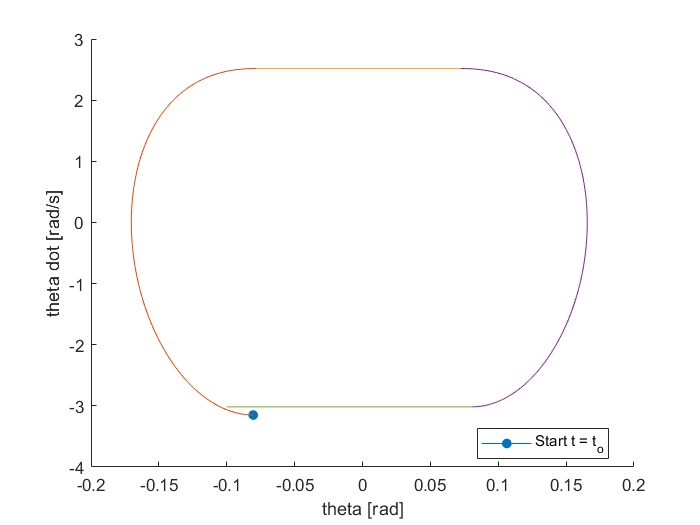

    hold on;

    plot(z_1(5,1),z_1(6,1),"Marker",".","MarkerSize",20);
    plot(z_1(5,:),z_1(6,:));
    plot(z_2(5,:),z_2(6,:));
    plot(z_3(5,:),z_3(6,:));
    plot(z_4(5,:),z_4(6,:));
    hold off;
    legend("Start t = t_o","Location", 'best');
    xlabel("theta [rad]");
    ylabel("theta dot [rad/s]");
end

## Analysis

u = [g,m,I,T_stance,amp_y,amp_x,t_o, body_length,T_air,x_foot];
eta = [y_i,y_dot_i, x_i, x_dot_i,th_i,th_dot_i];
lb = [0,-1,-1,4,-0.1,-6];
ub = [1,1,1,6,6,6];
 
minFun = @(x) x - onePeriod(x,u); 
ICs = lsqnonlin(minFun,eta,lb,ub)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


ICs =     1.0000   -0.3752    0.9998    4.0000   -0.1000   -2.8274
